% This live script can take the data from trackman then calculate
% and plot an approximate baseball pitch trajectory as well as the
% seam orientation, spin axis, velocity axis, and the hemisphere 
% plane as a function of time.

% The equation of seam line is from 
% http://www.darenscotwilson.com/spec/bbseam/bbseam.html.

% Coordinate System Specifications:
% The origin is at the tip of the home plate
% The positive y axis points to the pitcher
% The positive x axis points to the right of catcher's perspective
% The positive z axis points to the sky


% Define variables
PLATEYDIM = 17.0/12.0; % Front of the plate
ball_radius = 0.125; % Radius of a regular baseball in feet
diameter = 2*ball_radius; % Get ball diameter
diameter2 = 2*diameter; % Get 2*diameter


% Input initial baseball position (in feet)
relSide = 0.029947806;
releaseDistance = 54.7489757;
release_pos_y = releaseDistance;
relHeight = 6.67789545;

% Input the 9-parameter model
x0 = 0.057382798;
y0 = 50;
z0 = 6.384037468;
vx0 = 2.376676205;
vy0 = -134.9565751;
vz0 = -8.609936327;
ax0 = -6.567216039;
ay0 = 31.01559035;
az0 = -12.86456735;

% Input spin axis
a1 = -0.935469141;
a2 = -0.010097512;
a3 = -0.353264102;

% Handle exception
if ((a1^2 + a2^2 + a3^2) > 1.01 || (a1^2 + a2^2 + a3^2) < 0.99)
    ME = MException('myComponent:inputError', 'Please enter a unit vector.');
    throw(ME);
end

% Input spin rate
spin_rate = 2394.961622;

% Input seam angles
lat_d = 117.3088829;
long_d = 9.771264693;
theta_alpha_d = 0;


% Calculate the position of the ball as a function of time using equations of motion
% To do: Change it to a more appropriate model

% Compute time in seconds for baseball to travel from y=release_pos_y to y=y0
% Note that t1 is negative
% Solves equation y0 - release_pos_y = vy0*t1 + 0.5*ay0*t1*t1
t1 = (-vy0 - sqrt(vy0*vy0 - 2.0*ay0*(y0 - release_pos_y)))/ay0;

% Solve for position and velocity at release point (y0 = release_pos_y) in units of feet and seconds */
TM_x0 = 0.5*ax0*t1*t1 + vx0*t1 + x0;
TM_y0 = 0.5*ay0*t1*t1 + vy0*t1 + y0;
TM_z0 = 0.5*az0*t1*t1 + vz0*t1 + z0;
TM_vx0 = vx0 + ax0*t1;
TM_vy0 = vy0 + ay0*t1;
TM_vz0 = vz0 + az0*t1;

% Compute time in seconds for baseball to travel from y=release_pos_y to front of plate (y=1.417) */
t2 = (-TM_vy0 - sqrt(TM_vy0*TM_vy0 - 2.0*ay0*(TM_y0 - PLATEYDIM)))/ay0;

% Input time (sec)
time = 0;

% Compute (x,y,z) position of pitch as function of time
baseballx = TM_x0 + TM_vx0*time + 0.5*ax0*time*time;
basebally = TM_y0 + TM_vy0*time + 0.5*ay0*time*time;
baseballz = TM_z0 + TM_vz0*time + 0.5*az0*time*time;
fprintf('t = %f, x = %f, y = %f, z = %f \n', time, baseballx, basebally, baseballz); 

t = 0.000000, x = -0.029948, y = 54.748976, z = 6.677895 



position_x = baseballx;
position_y = basebally;
position_z = baseballz;
center = [position_x position_y position_z]; % Baseball center

% Calculate the velocity vector as a function of time
velocity_x = TM_vx0 + ax0*time;
velocity_y = TM_vy0 + ay0*time;
velocity_z = TM_vz0 + az0*time;
v_vector = [velocity_x velocity_y velocity_z];
fprintf('vx = %f, vy = %f, vz = %f \n', velocity_x, velocity_y, velocity_z); 

vx = 2.606842, vy = -136.043602, vz = -8.159062 



% Normalize
v_vector = v_vector./norm(v_vector);

% Calculate the hemisphere plane using equation of a plane: ax+by+cz=d
d = v_vector(1)*center(1) + v_vector(2)*center(2) + v_vector(3)*center(3);
xd = linspace(center(1) - diameter2, center(1) + diameter2);
yd = linspace(center(2) - diameter2, center(2) + diameter2);
[hemisphere_x, hemisphere_y] = meshgrid(xd, yd);
hemisphere_z = (d - (v_vector(1).*hemisphere_x + v_vector(2).*hemisphere_y))./v_vector(3); % Solve for z vertices data
fprintf('hemisphere plane equation: %fx + %fy + %fz = %f \n', v_vector(1), v_vector(2), v_vector(3), d); % Print the equation

hemisphere plane equation: 0.019124x + -0.998024y + -0.059855z = -55.041064 



% To do: Calculate the active zone


% Calculate the angle needed for the ball to rotate around the spin axis based on spin
% rate and time
rotation_angle = mod((spin_rate*360/60)*time, 360);
fprintf('rotation = %f \n', rotation_angle); 

rotation = 0.000000 


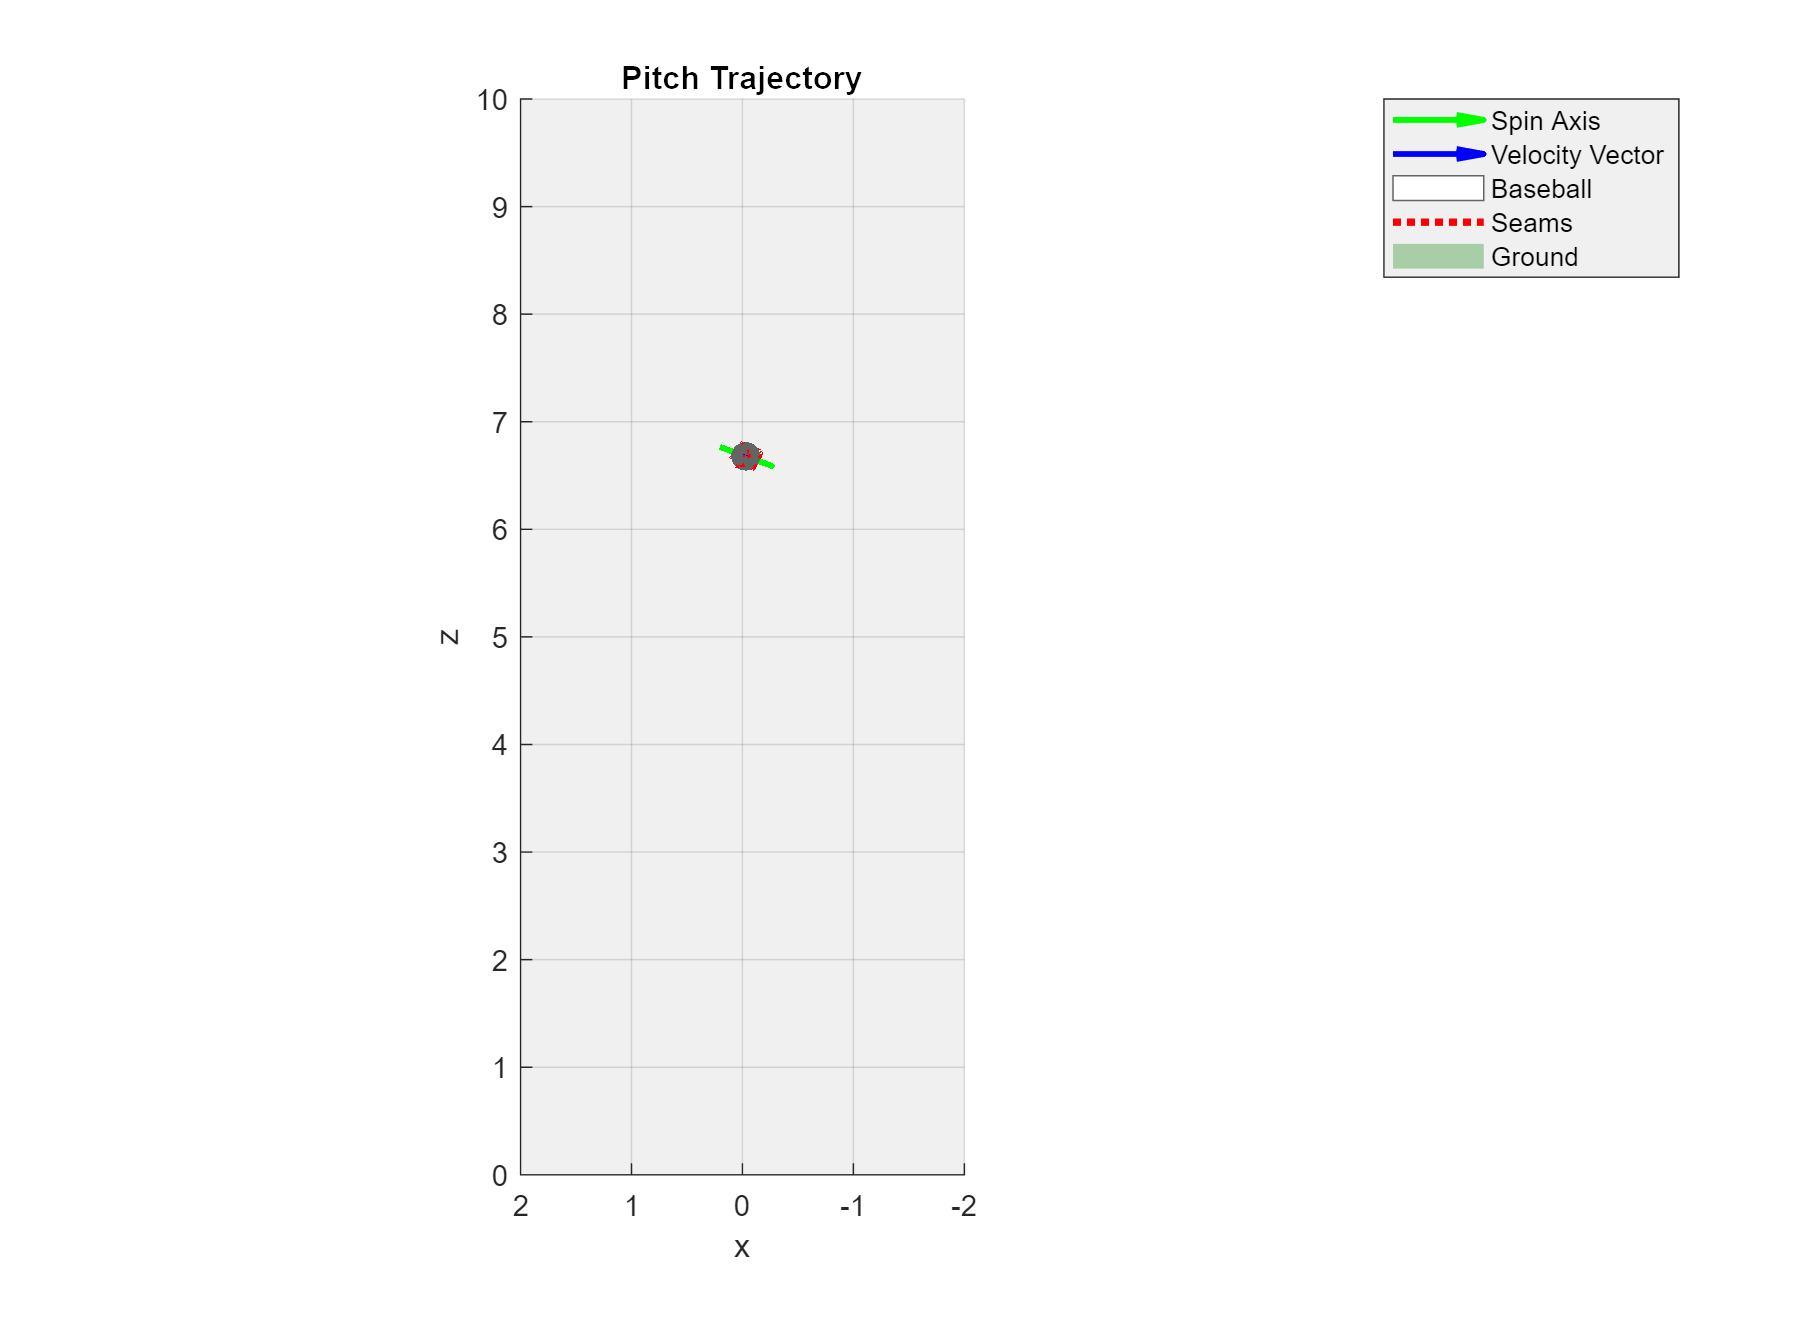


% Calculate the basis of baseball frame (for seam orientation):

% Handle corner case when seam lat = 0
% Set theta alpha = seam long and set seam long to 0 in this case
if lat_d == 0
   theta_alpha_d = long_d;
   long_d = 0;
end

% Convert to radians
lat = lat_d*pi/180.0;
long = long_d*pi/180.0;
theta_alpha = theta_alpha_d*pi/180.0;

% Define rotation matrices
Rlat = [ cos(lat), -sin(lat), 0;
         sin(lat),  cos(lat), 0;
                0,         0, 1];

Rlong = [  cos(long), 0, sin(long);
                   0, 1,         0;
          -sin(long), 0, cos(long)];

Ralpha = [  cos(theta_alpha), 0, sin(theta_alpha);
                           0, 1,                0;
           -sin(theta_alpha), 0, cos(theta_alpha)];

% Calculate theta k and k vector based on spin axis
if a2 == 1
    k = 0;
    Rk = eye(3); % special case, k is undefined, Rk not needed
    k_vector = [1 1 1]; % Use a random vector for k_vector since undefined
elseif a2 == -1
    k = pi;
    % Another special case, k is undefined, rotate around z axis for pi
    Rk = [ cos(k), -sin(k), 0;
           sin(k),  cos(k), 0;
                0,       0, 1];
    k_vector = [0 0 1]; % Make k_vector z axis 
else
    if a2 >= 0
        k = asin(sqrt(a3^2 + a1^2));
        k_vector = [a3/(a1^2 + a3^2)^(1/2), 0, -a1/(a1^2 + a3^2)^(1/2)];
    elseif a2 < 0
        k = pi - asin(sqrt(a3^2 + a1^2));
        k_vector = [a3/(a1^2 + a3^2)^(1/2), 0, -a1/(a1^2 + a3^2)^(1/2)];
    end
    
    % Rotation matrix for Rk
    k1 = k_vector(1);
    k2 = k_vector(2);
    k3 = k_vector(3);
    
    Rk = [  cos(k) + (k1^2)*(1 - cos(k)),   k1*k2*(1 - cos(k)) - k3*sin(k), k1*k3*(1 - cos(k)) + k2*sin(k);
            k2*k1*(1 - cos(k)) + k3*sin(k),   cos(k) + (k2^2)*(1 - cos(k)), k2*k3*(1 - cos(k)) - k1*sin(k);
            k3*k1*(1 - cos(k)) - k2*sin(k), k3*k2*(1 - cos(k)) + k1*sin(k),  cos(k) + (k3^2)*(1 - cos(k))];
end

% Calculate for seam rotations on the ball
temp = Rk*Rlat;
y2 = temp(:, 2); % Rotation axis for seam long
z1 = Rk(:, 3); % Rotation axis for seam lat
k_d = k*180/pi; % Convert k to degree 
spin_axis = [a1 a2 a3]; % Get spin axis

% Define the equation for basis of standard seam orientation
P4 = Rk*Ralpha*Rlat*Rlong;


% Plot:
figure
hold on

% Draw spin axis
quiver3(center(1) - a1*diameter, center(2) - a2*diameter, center(3) - a3*diameter, a1, a2, a3, diameter2, 'g', 'LineWidth', 2); % scale the starting point according to ball_radius

% Draw velocity vector
quiver3(center(1) - v_vector(1)*diameter, center(2) - v_vector(2)*diameter, center(3) - v_vector(3)*diameter, v_vector(1), v_vector(2), v_vector(3), diameter2, 'b', 'LineWidth', 2);

% Draw a sphere representing baseball
[X,Y,Z] = sphere(40);

% Account for axes offset
% baseballx = y, basebally = z, baseballz = x
% Also rotate to align the axes
ballx = Y;
bally = Z;
ballz = X;

s = surf(double(center(1) + ball_radius*ballx), double(center(2) + ball_radius*bally), double(center(3) + ball_radius*ballz));
s.FaceColor = 'white'; % Ball color
s.EdgeColor = [100/255 100/255 100/255]; % Grid color
s.FaceAlpha = 1.0; % Transparency

% Rotate the ball to the seam orientation to match the grid
rotate(s, k_vector, k_d, center);
rotate(s, z1, lat_d, center);
rotate(s, y2, long_d, center);
rotate(s, spin_axis, theta_alpha_d, center);

% Draw seams
alpha = 1:1:360;
% Convert to radian
alpha_r = alpha*pi/180.0;

% Calculate seam points
seamx = (1/13)*ball_radius*(9*cos(alpha_r) - 4*cos(3*alpha_r));
seamy = (1/13)*ball_radius*(9*sin(alpha_r) + 4*sin(3*alpha_r));
seamz = (12/13)*ball_radius*cos(2*alpha_r);

% Account for axes offset
% baseballx = y, basebally = z, baseballz = x
% Also rotate to align the axes
adjustedx = seamy;
adjustedy = seamz;
adjustedz = seamx;

seam_line = [adjustedx; adjustedy; adjustedz];
seam_line = P4*seam_line; % Rotate to the basis

% Add to the ball position
seamx = center(1) + seam_line(1, :);
seamy = center(2) + seam_line(2, :);
seamz = center(3) + seam_line(3, :);

% Plot seam line
p = plot3(seamx, seamy, seamz, '-r', 'LineWidth', 2.5);
p.LineStyle = ':';

% Rotate the ball and the seams around spin axis as a function of time
rotate(s, spin_axis, rotation_angle, center);
rotate(p, spin_axis, rotation_angle, center);


% Label and adjust settings
xlabel('x')
ylabel('y')
zlabel('z')
grid on
title('Pitch Trajectory')
set(gca,'color', [240/255 240/255 240/255]) % Background color
axis equal

% Adjust view
view_azimuth = 180;
view_elevation =  0;
view([view_azimuth view_elevation]) % View (default is pitcher's perspective)
axis([-2 2 0 60 0 10]) % Fix the axes

% Adjust figure size
figure_x0 = 10;
figure_y0 = 10;
width = 825;
height = 600;
set(gcf, 'position', [figure_x0, figure_y0, width, height]);

% Change the color of the x-y plane to be dark green
x_lim = get(gca, 'XLim');
y_lim = get(gca, 'YLim');
z_lim = get(gca, 'YLim');
pat = patch([x_lim(1), x_lim(2), x_lim(2), x_lim(1)], [y_lim(1), y_lim(1), y_lim(2), y_lim(2)], [z_lim(1) z_lim(1) z_lim(1) z_lim(1)], [0 0.5 0]);
pat.EdgeColor = 'none';
pat.FaceAlpha = 0.3;

% Label
legend('Spin Axis', 'Velocity Vector', 'Baseball', 'Seams', 'Ground')

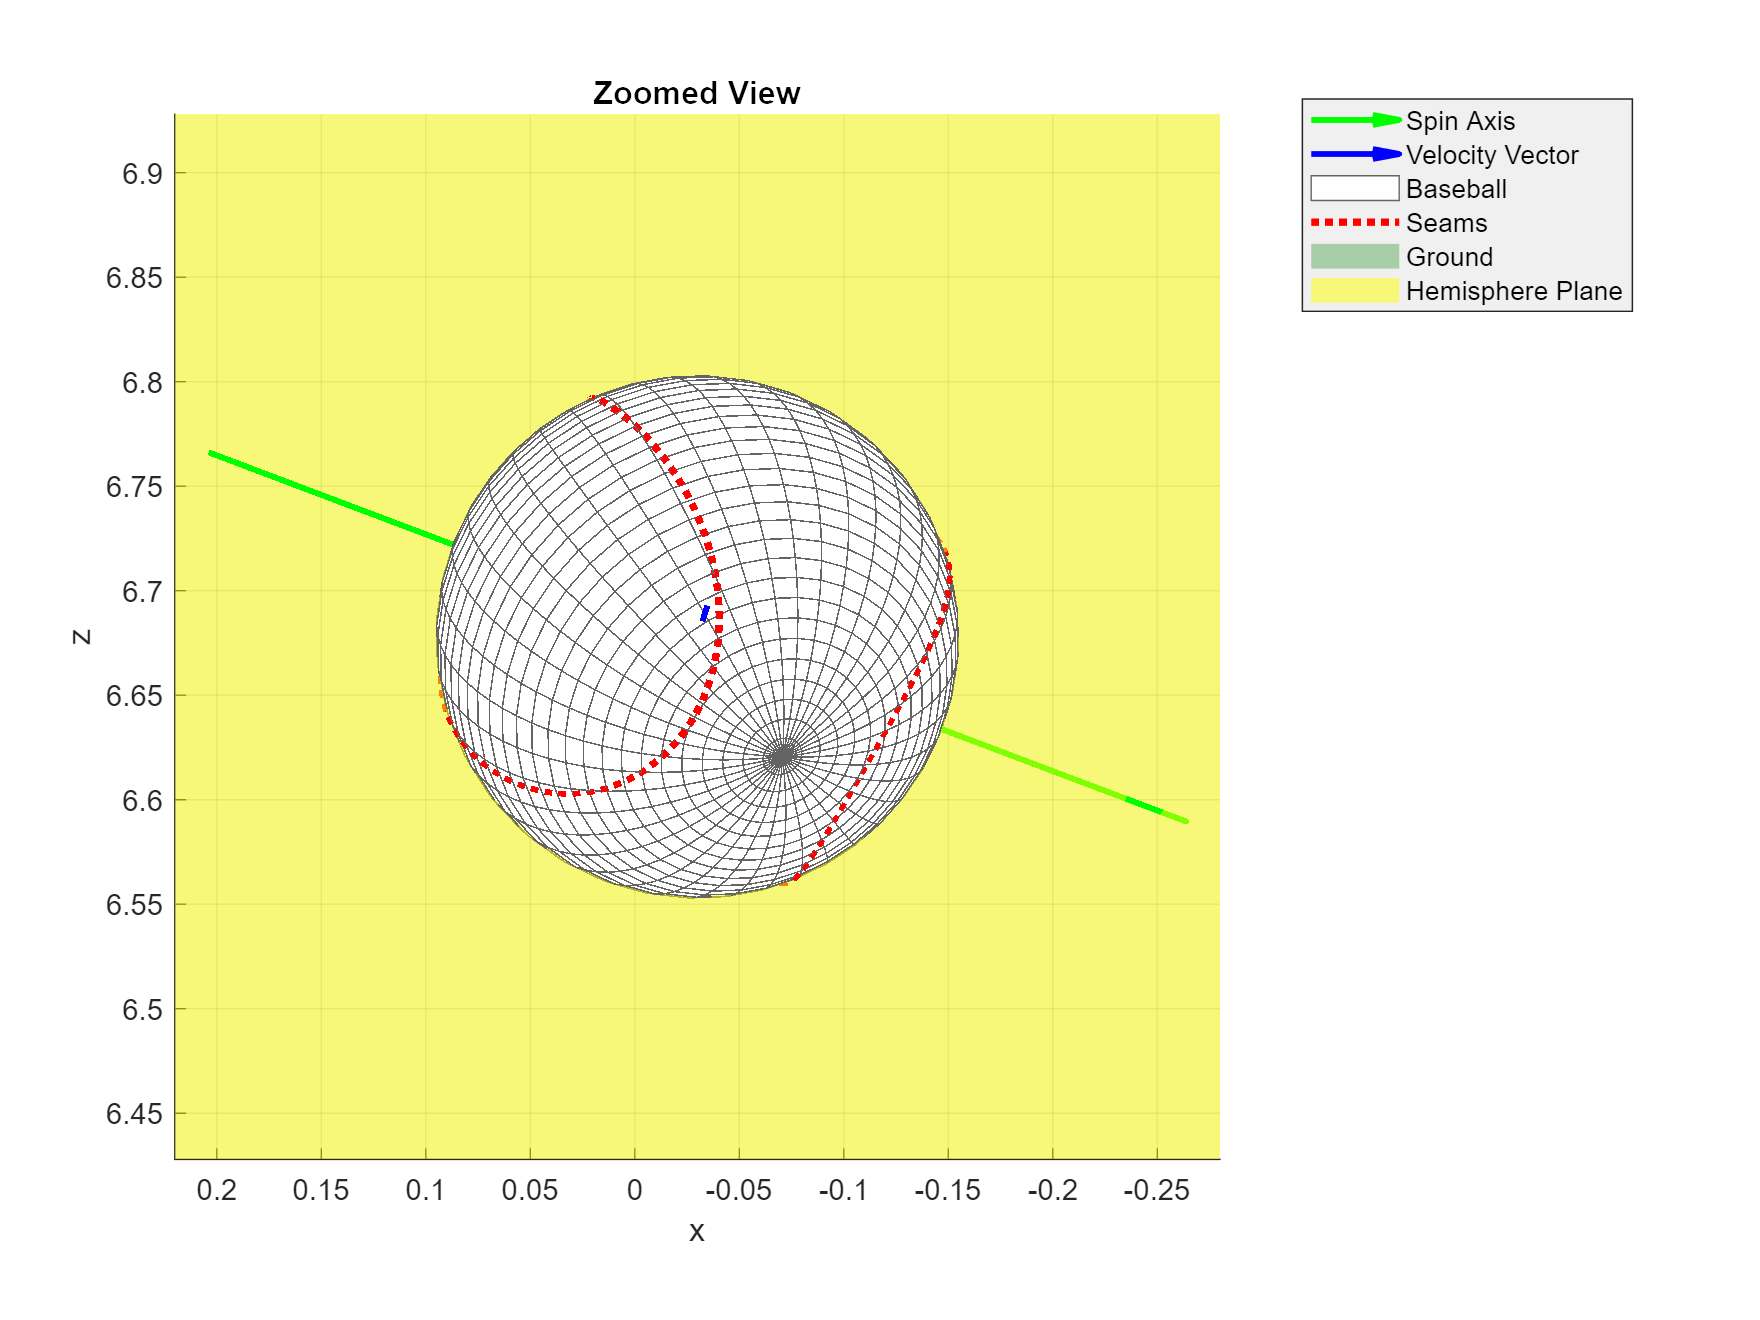

% Section break to get a second plot

% Zoom in to the baseball
title('Zoomed View')
xlim([center(1) - diameter center(1) + diameter]);
ylim([center(2) - diameter center(2) + diameter]);
zlim([center(3) - diameter center(3) + diameter]);

% Plot the hemisphere plane
surf(hemisphere_x, hemisphere_y, hemisphere_z, 'EdgeColor', 'none', 'FaceColor', 'y', 'FaceAlpha', 0.5);
legend('Spin Axis', 'Velocity Vector', 'Baseball', 'Seams', 'Ground', 'Hemisphere Plane')

% To do: Plot the active zone
